## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# TRAJECTORY PLANNING

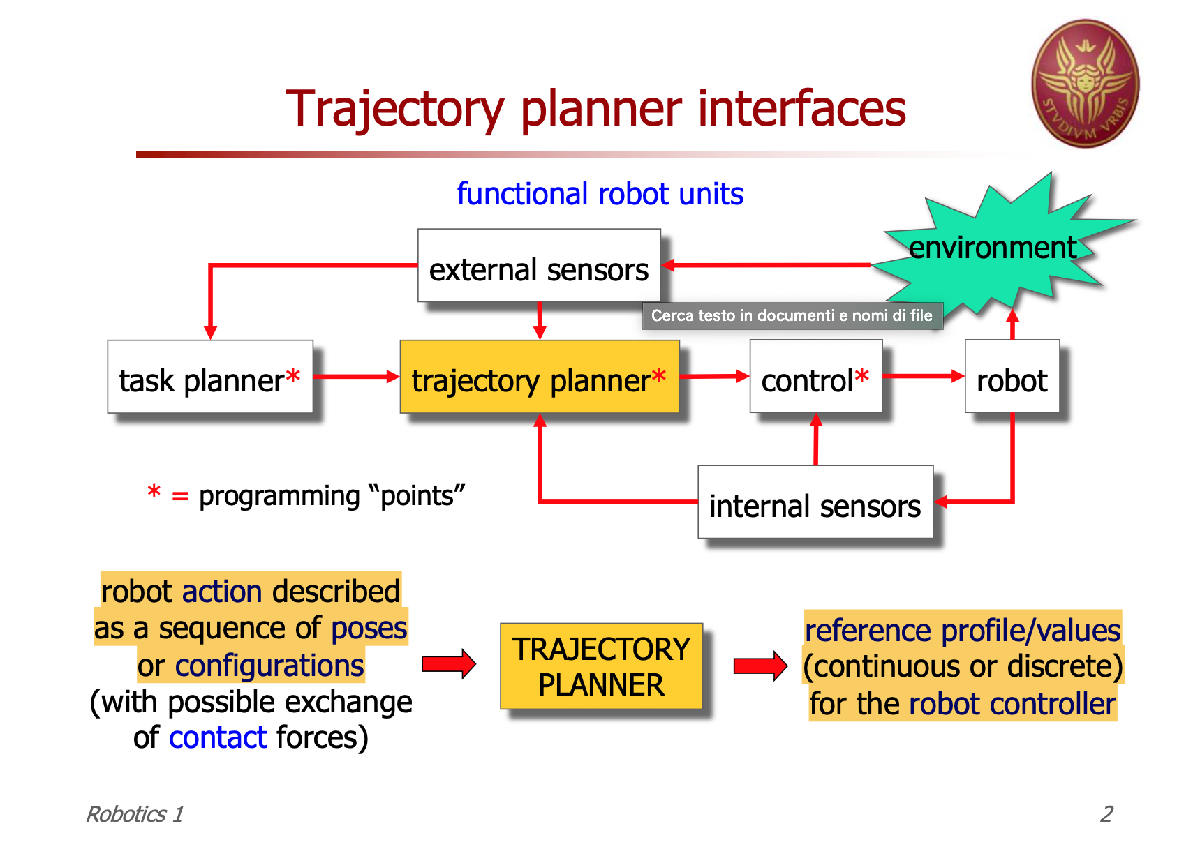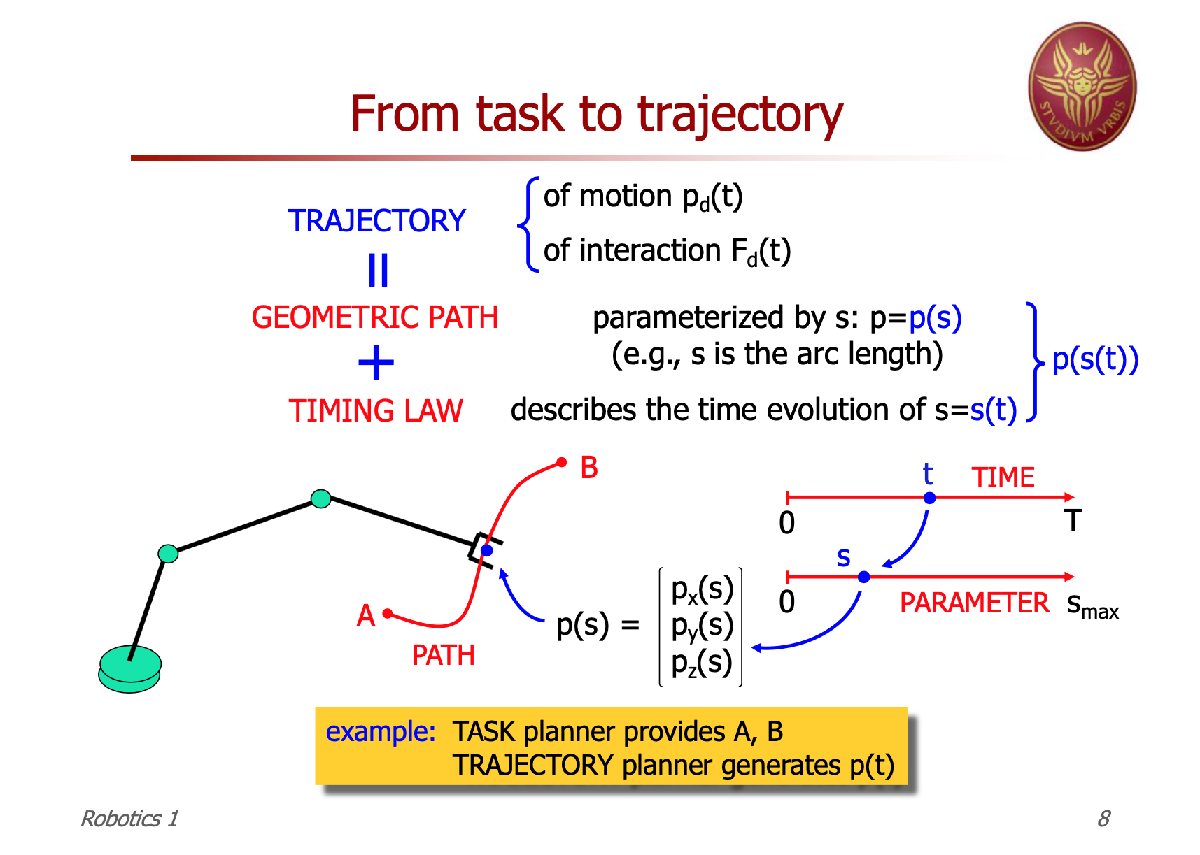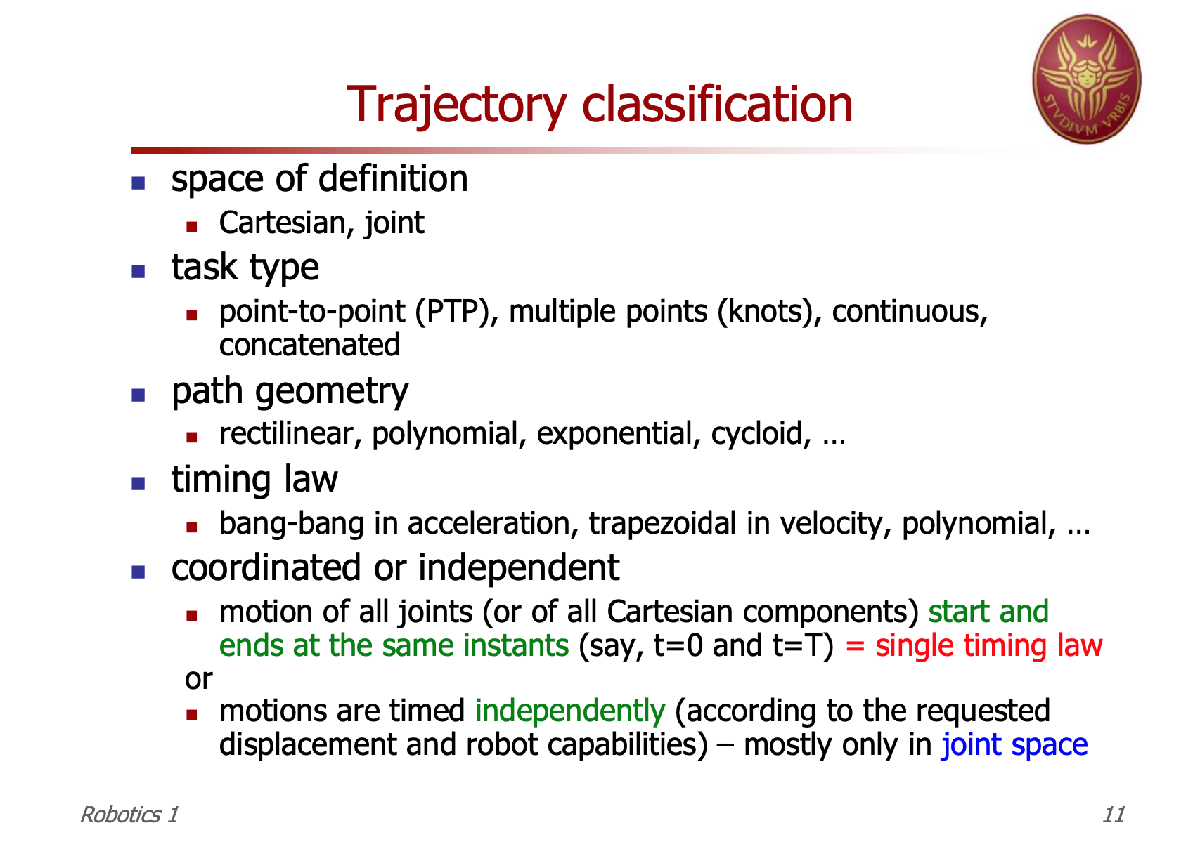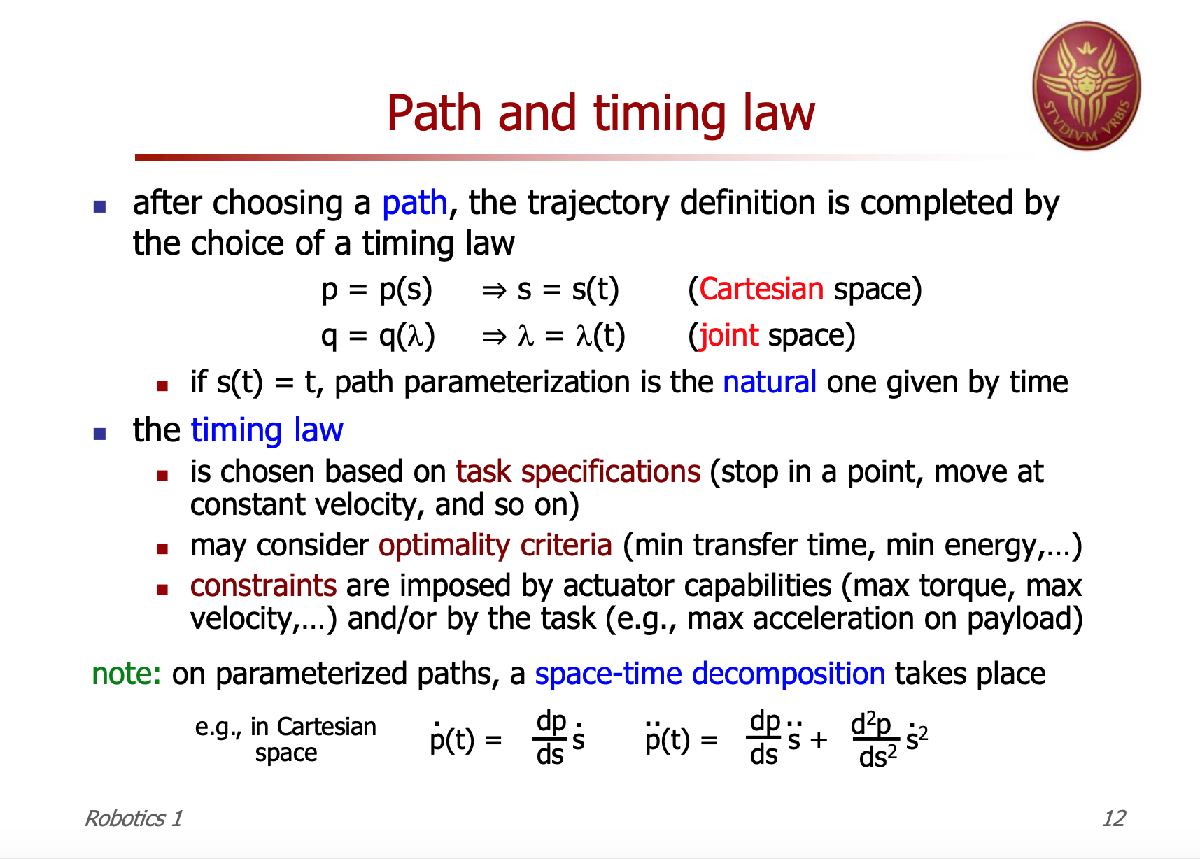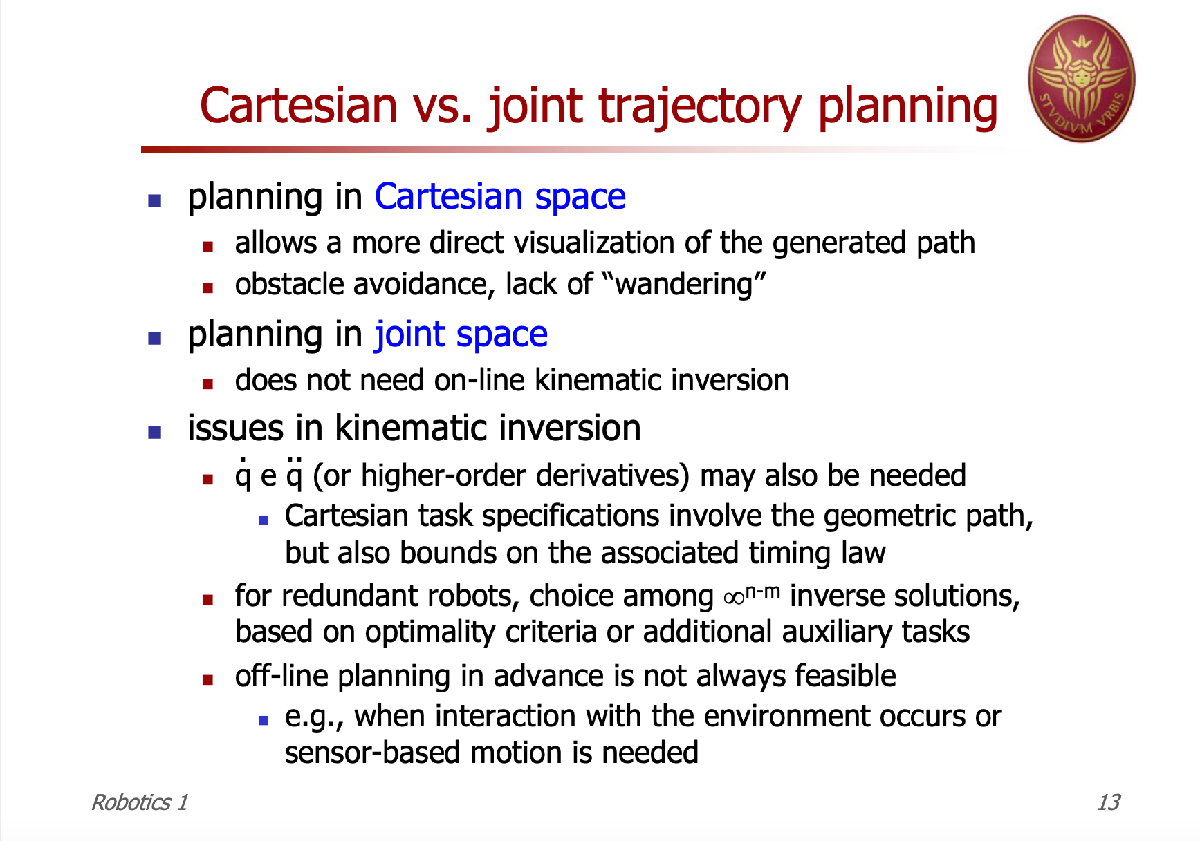

# TRAJECTORY PLANNING IN JOINT SPACE

#### CUBIC POLYNOMIAL INTERPOLATION - PTP

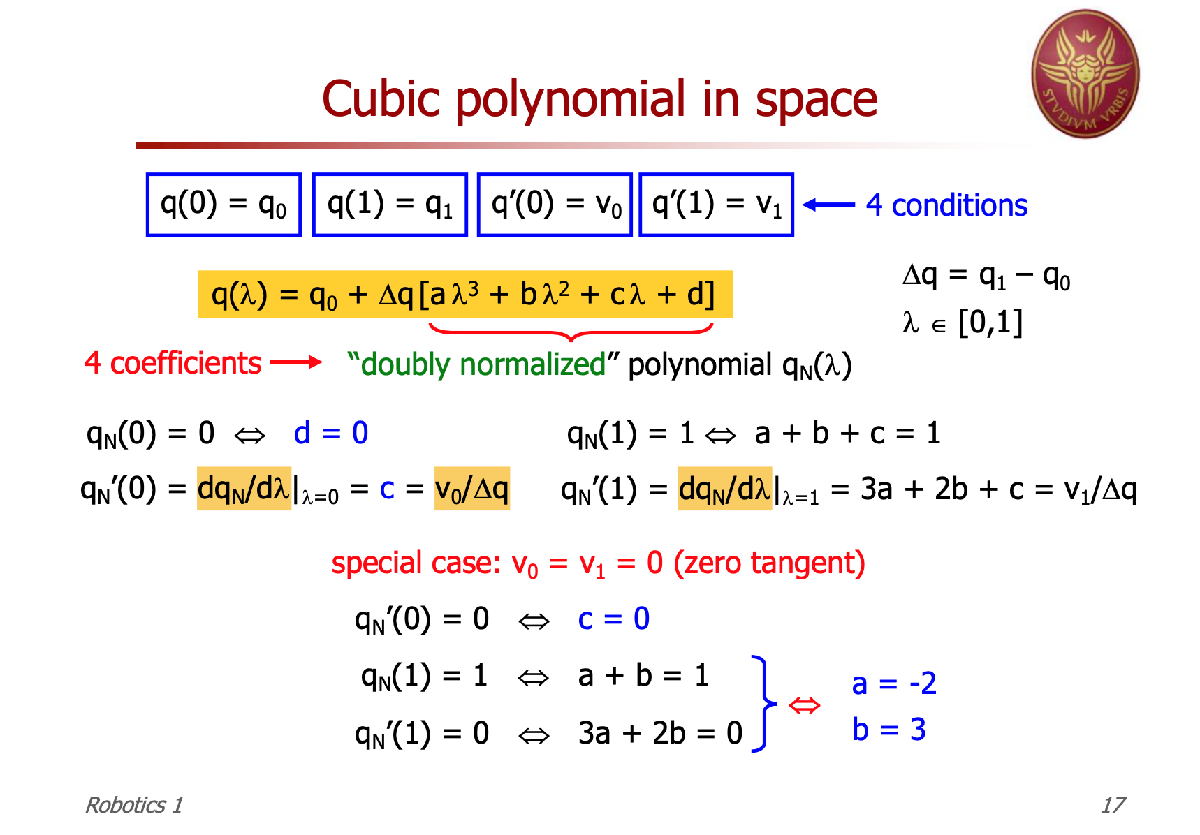

% if t=[start,end]=[0,1] -> l(t)=t

% enlarging the duration reduces the desired VELOCITY
% of a factor of T

% anlarging the duration reduces the desired ACCELERATION
% of a factor of T^2

% changing T -> out velocity q_dot_0/T, out acceleration q_ddot_0/T^2
% thus:
% q_dot = q_dot_desired * T
% q_ddot = q_ddot_desired * T^2

start_time=0;
end_time=sqrt(25.8/4)

end_time = 2.5397

T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

[q0, q1] = deal(0, 3);
[q_dot_0, q_dot_1] = deal(-2, 0);

cubic_poly_traj = time_vector;

lambda_vector = time_vector ./ T;

% TRAJECTORY
for t=1:length(lambda_vector)
    cubic_poly_traj(t) = SR_ROBO.ptp_cubic(q0, q1,q_dot_0, q_dot_1,lambda_vector(t));
end

% plot(time_vector,cubic_poly_traj)
% title('CUBIC POLYNOMIAL IN TIME')
% xlabel('Time (s)')
% ylabel('q (rad)')

disp('INTERPOLATION OF TRAJECTORY AND VELOCITY')

INTERPOLATION OF TRAJECTORY AND VELOCITY


disp('no control on acceleration')

no control on acceleration


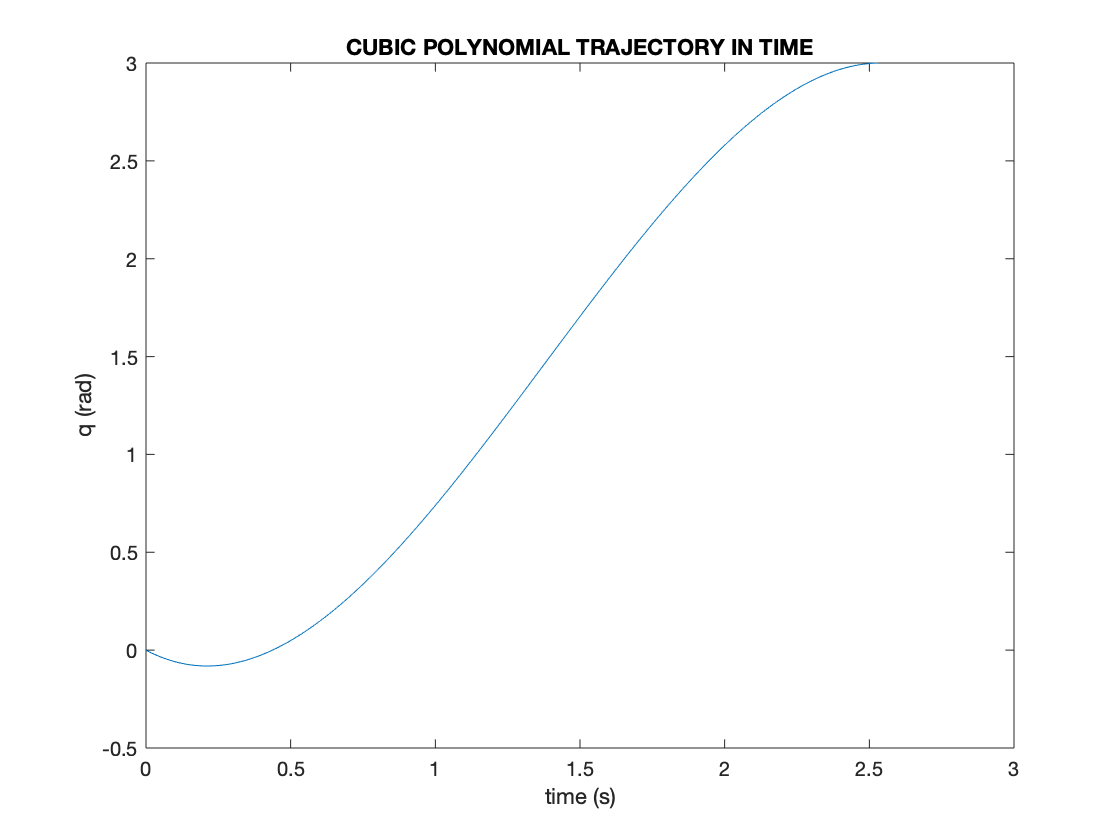


plot(time_vector,cubic_poly_traj)
title('CUBIC POLYNOMIAL TRAJECTORY IN TIME')
xlabel('time (s)')
ylabel('q (rad)')

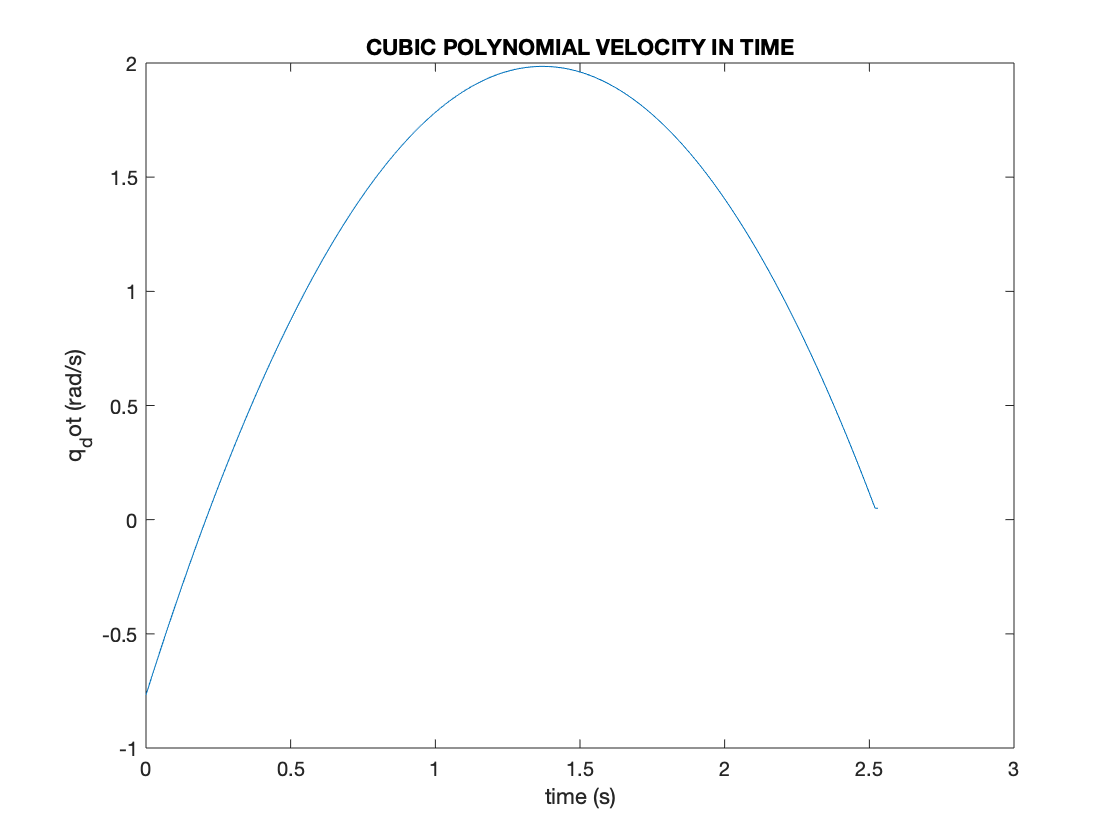


% VELOCITY
cubic_poly_vel = time_vector;


for t=1:length(lambda_vector)-1
    cubic_poly_vel(t) = (cubic_poly_traj(t+1) - cubic_poly_traj(t))/time_step;
end
cubic_poly_vel(length(lambda_vector))=cubic_poly_vel(length(lambda_vector)-1);

plot(time_vector,cubic_poly_vel)
title('CUBIC POLYNOMIAL VELOCITY IN TIME')
xlabel('time (s)')
ylabel('q_dot (rad/s)')

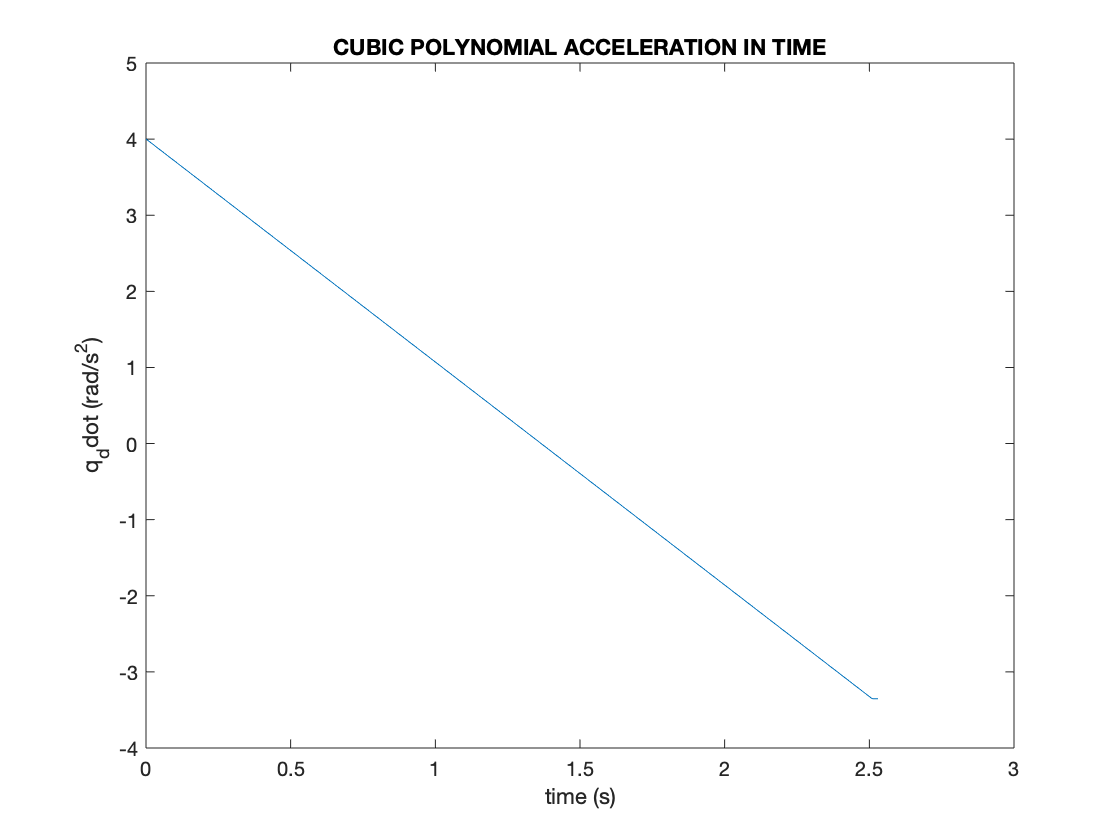


% ACCELERATION
cubic_poly_acc = time_vector;

for t=1:length(lambda_vector)-2
    % same cubic_poly_acc(t) = (cubic_poly_traj(t+2)- 2 * cubic_poly_traj(t+1) + cubic_poly_traj(t))/(time_step)^2;
    cubic_poly_acc(t) = (cubic_poly_vel(t+1) - cubic_poly_vel(t))/time_step;
end
cubic_poly_acc(length(lambda_vector)-1)=cubic_poly_acc(length(lambda_vector)-2);
cubic_poly_acc(length(lambda_vector))=cubic_poly_acc(length(lambda_vector)-1);

plot(time_vector,cubic_poly_acc)
title('CUBIC POLYNOMIAL ACCELERATION IN TIME')
xlabel('time (s)')
ylabel('q_ddot (rad/s^2)')

#### QUINTIC POLYNOMIAL INTERPOLATION - PTP

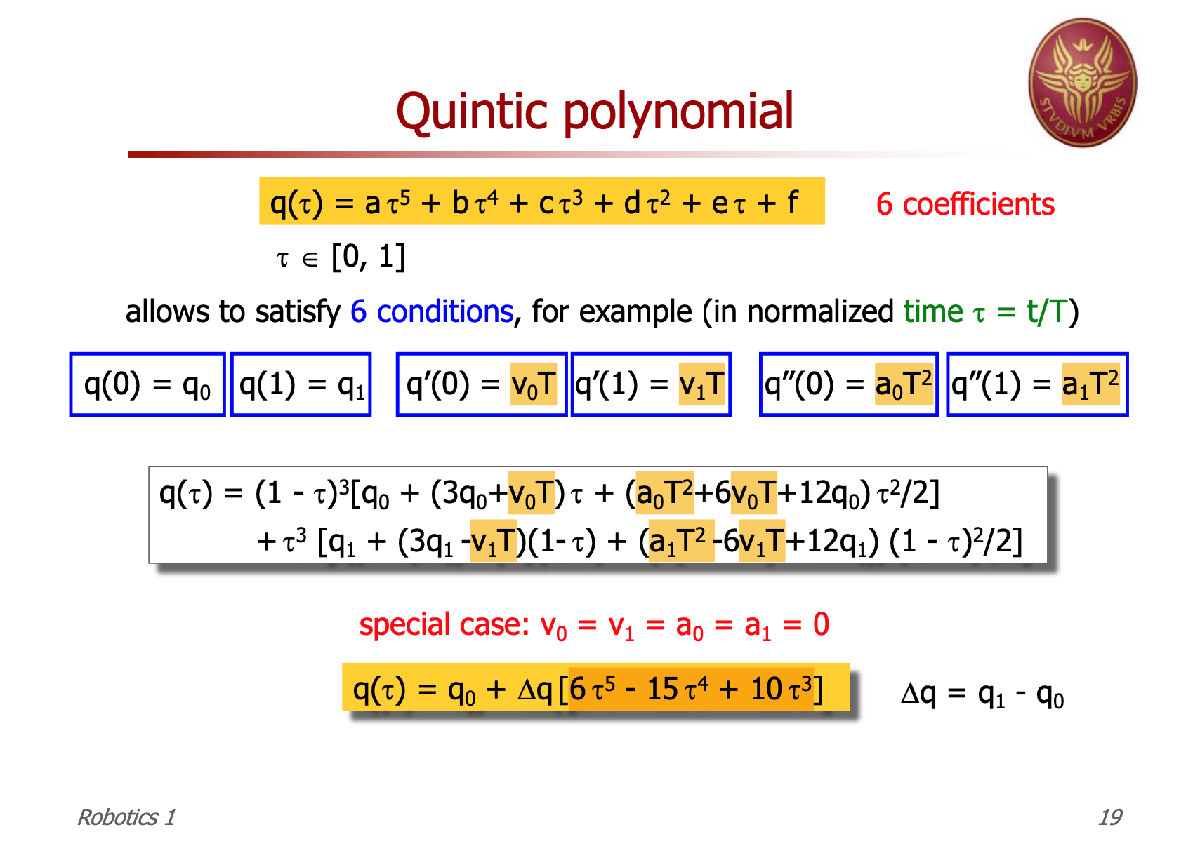

disp('INTERPOLATION OF TRAJECTORY, VELOCITY AND ACCELERATION')

INTERPOLATION OF TRAJECTORY, VELOCITY AND ACCELERATION


disp('control on acceleration')

control on acceleration


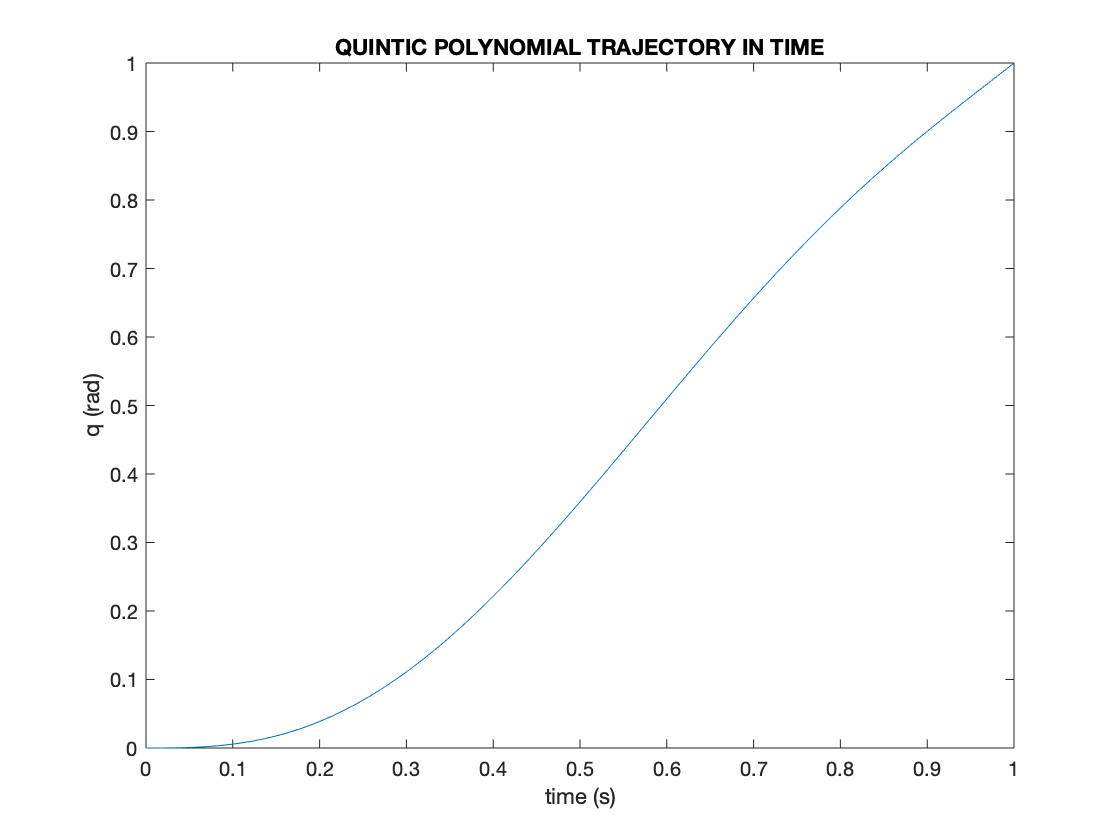


% if t=[start,end]=[0,1] -> l(t)=t

% enlarging the duration reduces the desired VELOCITY
% of a factor of T

% anlarging the duration reduces the desired ACCELERATION
% of a factor of T^2

% changing T -> out velocity q_dot_0/T, out acceleration q_dot_0/T^2
% thus:
% q_dot = q_dot_desired * T
% q_ddot = q_ddot_desired * T^2

start_time=0;
end_time=1;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

%%%%% TASK REQUIREMENTS %%%%%
[q_in,q_fin]=deal(0,1);
[q_dot_0_in, q_dot_1_fin]=deal(0,1);
[q_ddot_0_in, q_dodt_1_fin]=deal(0,1);

[q0, q1] = deal(q_in,q_fin);
[q_dot_0, q_dot_1] = deal(q_dot_0_in*T, q_dot_1_fin*T);
[q_ddot_0, q_ddot_1] = deal(q_ddot_0_in*T^2, q_dodt_1_fin*T^2);

lambda_vector = time_vector ./ T;

quintic_poly_traj = time_vector;

%TRAJECTORY
for t=1:length(lambda_vector)
    quintic_poly_traj(t) = SR_ROBO.ptp_quintic(q0, q1,q_dot_0, q_dot_1,q_ddot_0, q_ddot_1,lambda_vector(t));
end

% plot(time_vector,quintic_poly_traj)
% title('QUINTIC POLYNOMIAL IN TIME')
% xlabel('Time (s)')
% ylabel('q (rad)')

plot(time_vector,quintic_poly_traj)
title('QUINTIC POLYNOMIAL TRAJECTORY IN TIME')
xlabel('time (s)')
ylabel('q (rad)')

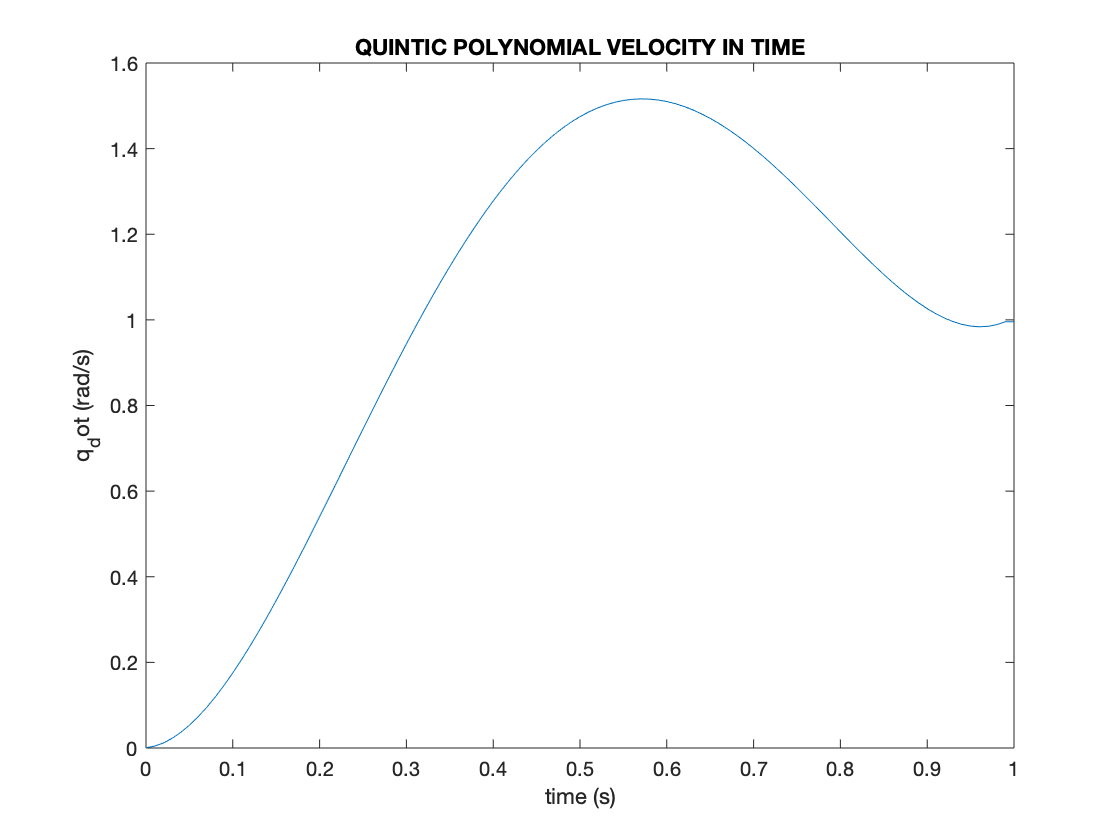


% VELOCITY
quintic_poly_vel = time_vector;

for t=1:length(lambda_vector)-1
    quintic_poly_vel(t) = (quintic_poly_traj(t+1) - quintic_poly_traj(t))/time_step;
end
quintic_poly_vel(length(lambda_vector))=quintic_poly_vel(length(lambda_vector)-1);

plot(time_vector,quintic_poly_vel)
title('QUINTIC POLYNOMIAL VELOCITY IN TIME')
xlabel('time (s)')
ylabel('q_dot (rad/s)')

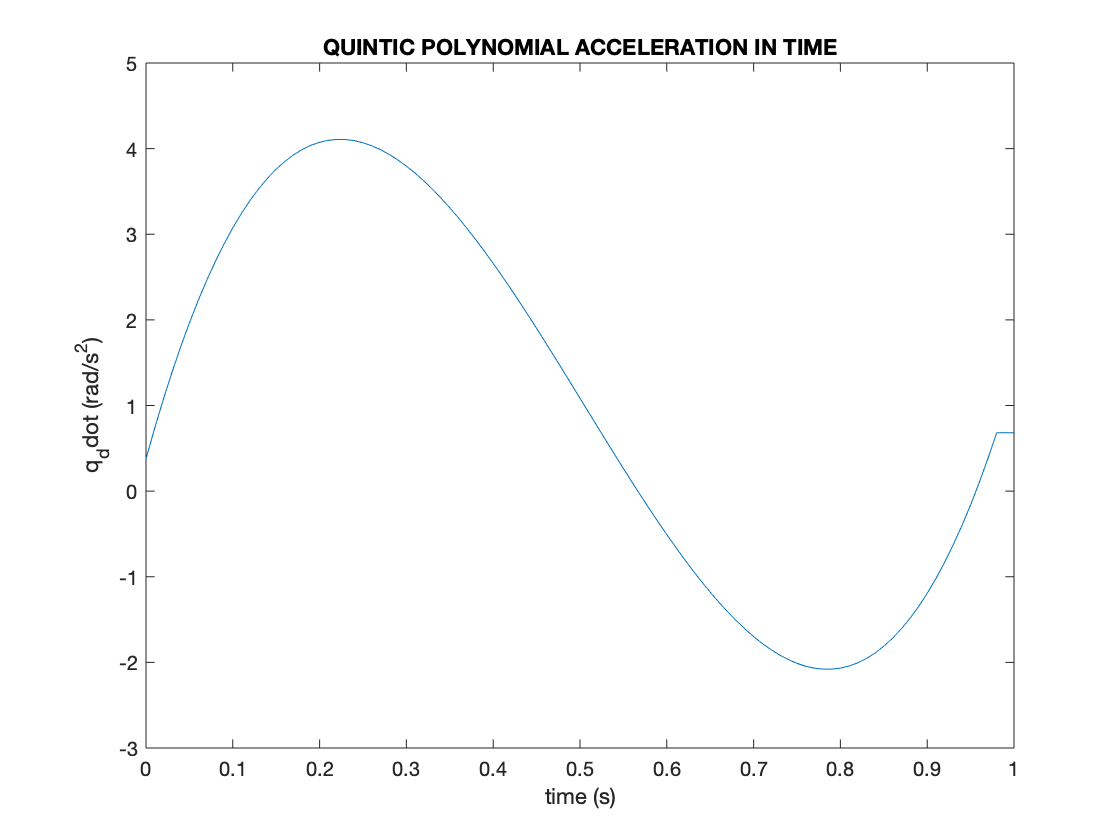


% ACCELERATION
quintic_poly_acc = time_vector;

for t=1:length(lambda_vector)-2
    quintic_poly_acc(t) = (quintic_poly_vel(t+1) - quintic_poly_vel(t))/time_step;
end
quintic_poly_acc(length(lambda_vector)-1)=quintic_poly_acc(length(lambda_vector)-2);
quintic_poly_acc(length(lambda_vector))=quintic_poly_acc(length(lambda_vector)-1);

plot(time_vector,quintic_poly_acc)
title('QUINTIC POLYNOMIAL ACCELERATION IN TIME')
xlabel('time (s)')
ylabel('q_ddot (rad/s^2)')

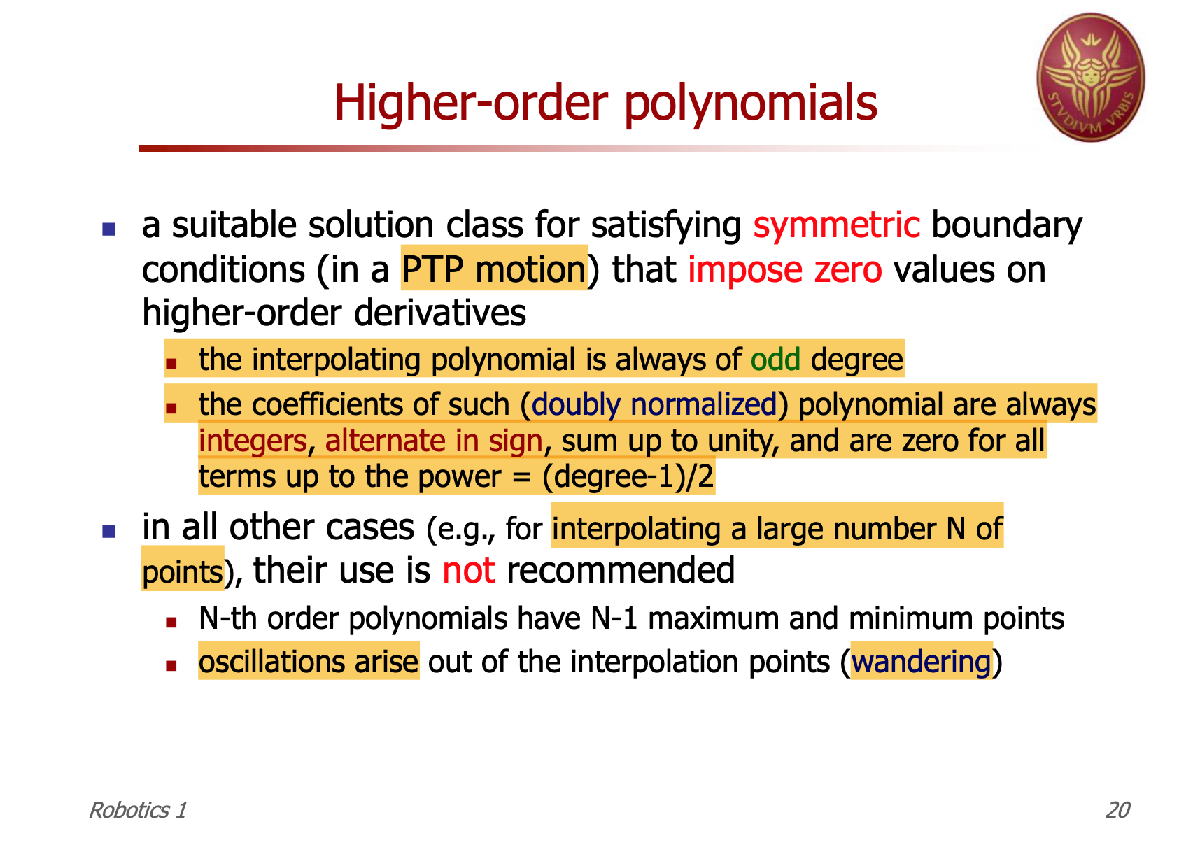

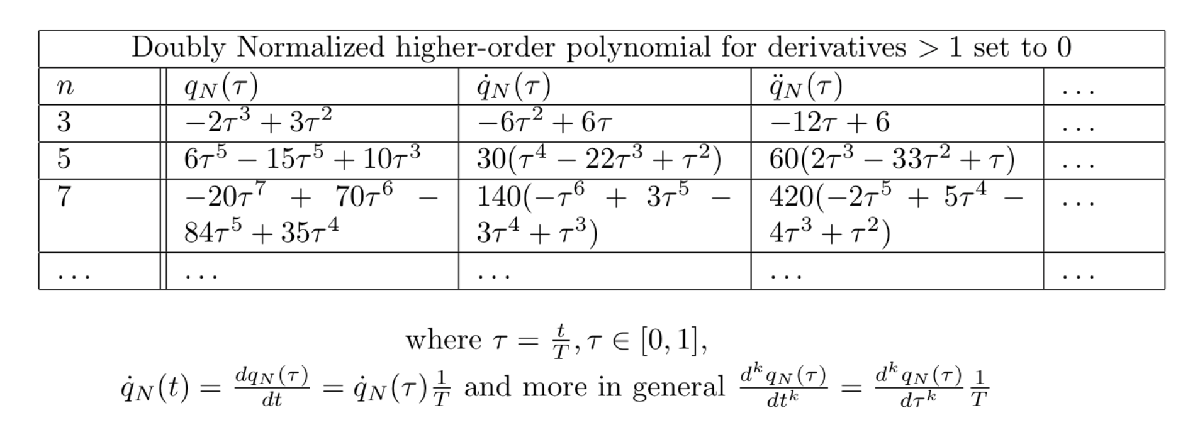

#### HIGHER POLYNOMIAL INTERPOLATION - PTP

[q0, q1] = deal(q_in,q_fin);

Dq = q1 - q0;

order = 7;

l = sym('l','real');

f = SR_ROBO.rest_to_rest_higher_order(order)

$$f = -20\,l^{7}+70\,l^{6}-84\,l^{5}+35\,l^{4}$$

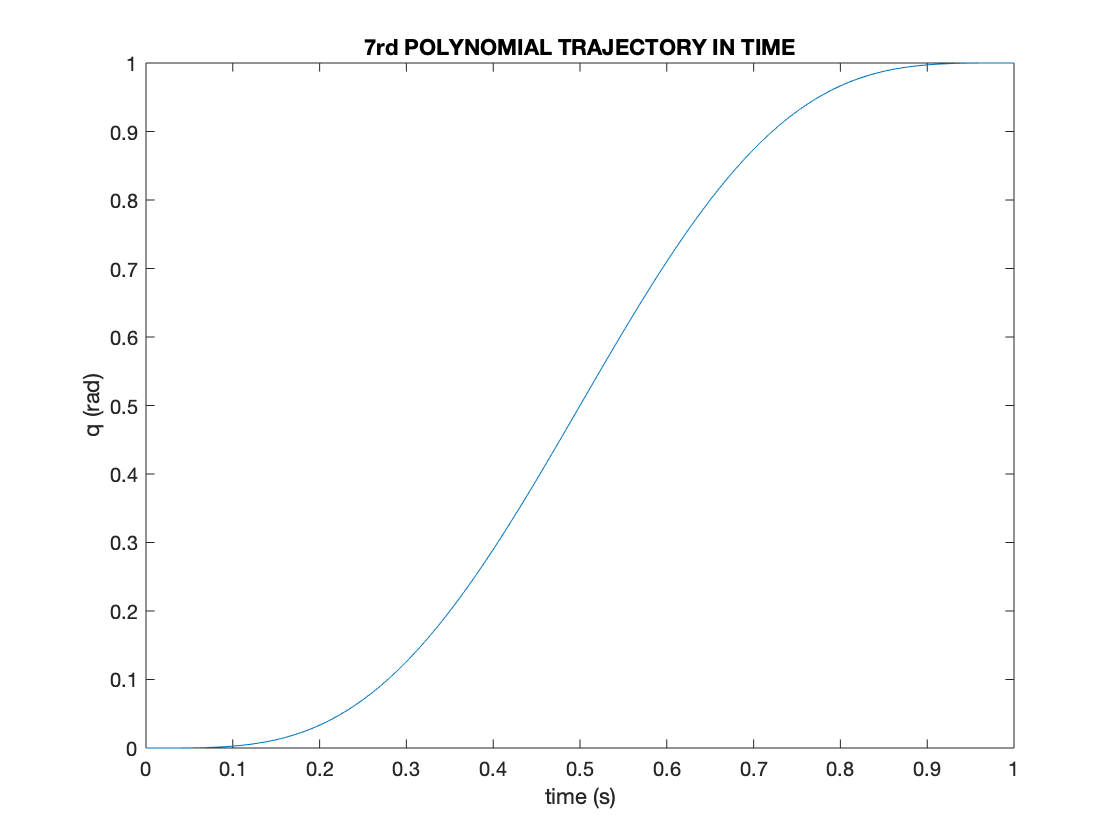


higher_poly_traj = time_vector;

%TRAJECTORY
for t=1:length(lambda_vector)
    higher_poly_traj(t) = q0 + Dq * double(subs(f,l,lambda_vector(t)));
end

plot(time_vector,higher_poly_traj)
title(string(order)+'rd POLYNOMIAL TRAJECTORY IN TIME')
xlabel('time (s)')
ylabel('q (rad)')

# CUBIC SPLINE - MULTI MINIMUM CURVATURE

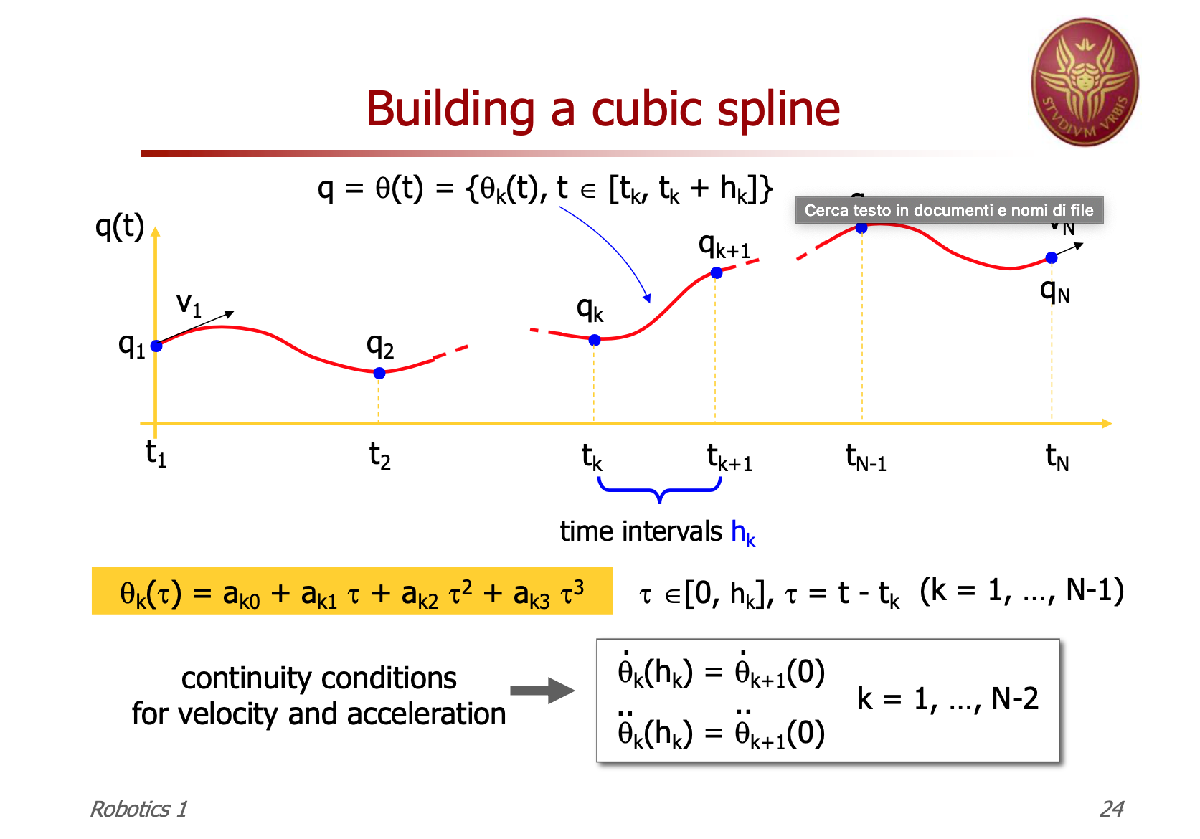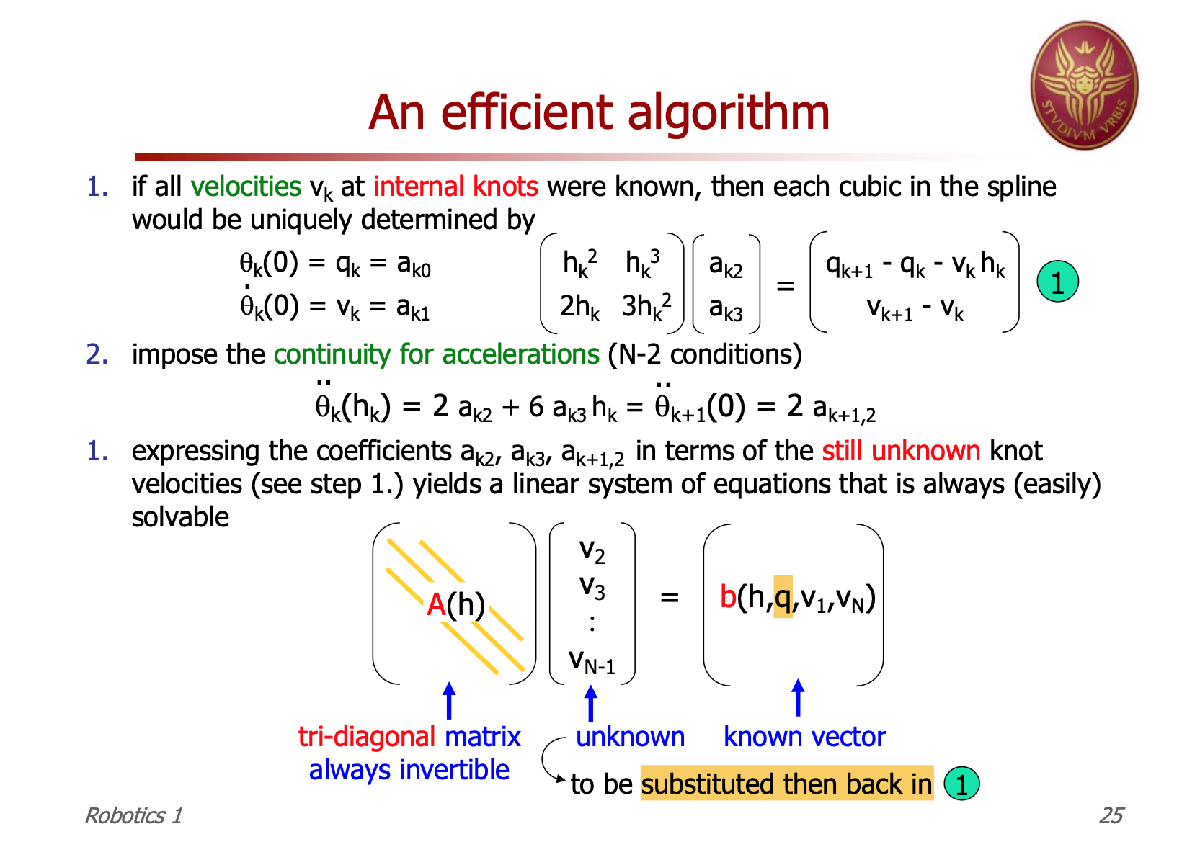

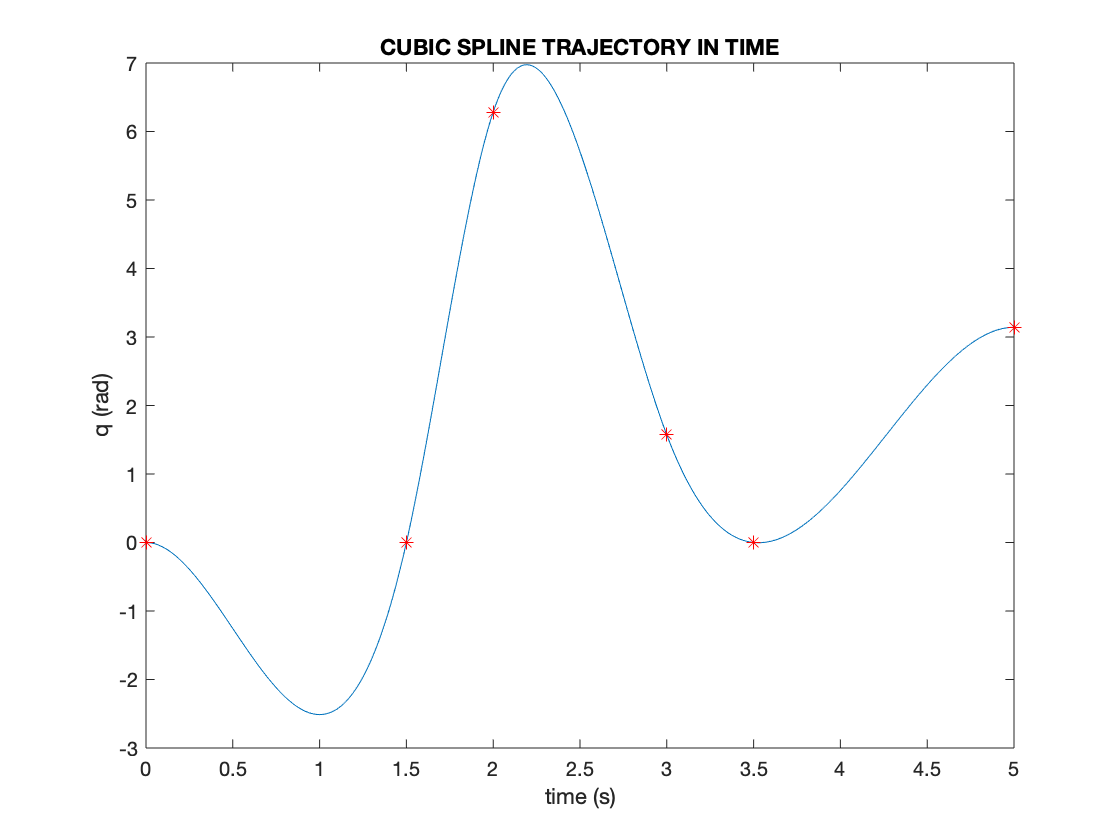

% if t=[start,end]=[0,1] -> l(t)=t

% enlarging the duration reduces the desired VELOCITY
% of a factor of T

% anlarging the duration reduces the desired ACCELERATION
% of a factor of T^2

% changing T -> out velocity q_dot_0/T, out acceleration q_dot_0/T^2
% thus:
% q_dot = q_dot_desired * T
% q_ddot = q_ddot_desired * T^2

start_time=0;
end_time=5;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

lambda_vector = time_vector ./ T;

%%%%% TASK REQUIREMENTS %%%%%
% KNOT: TIME [0,1] - POSITION - VELOCITY
knots = {{0, 0, 0 * T}, ...
    {0.3, 0, 'none'}, ... % fake knots
    {0.4, 2*pi, 'none'}, ... # intermediate knots whatever velocity
    {0.6, pi/2, 'none'}, ...
    {0.7, 0, 'none'}, ... % fake knots
    {1, pi, 0 * T}};

% a_k = ( p_k+2 - 2 * p_k+1 + p_k ) / dt ^ 2 ???

coeff = SR_ROBO.cubic_spline_coefficients(knots);

cubic_spline_traj = time_vector;

%TRAJECTORY
for t=1:length(lambda_vector)
    cubic_spline_traj(t) = SR_ROBO.cubic_spline(coeff,knots,lambda_vector(t));
end

plot(time_vector,cubic_spline_traj)
title('CUBIC SPLINE TRAJECTORY IN TIME')
xlabel('time (s)')
ylabel('q (rad)')
hold on
for i=1:length(knots)
    plot(knots{i}{1}*T,knots{i}{2},'r*')
end
hold off

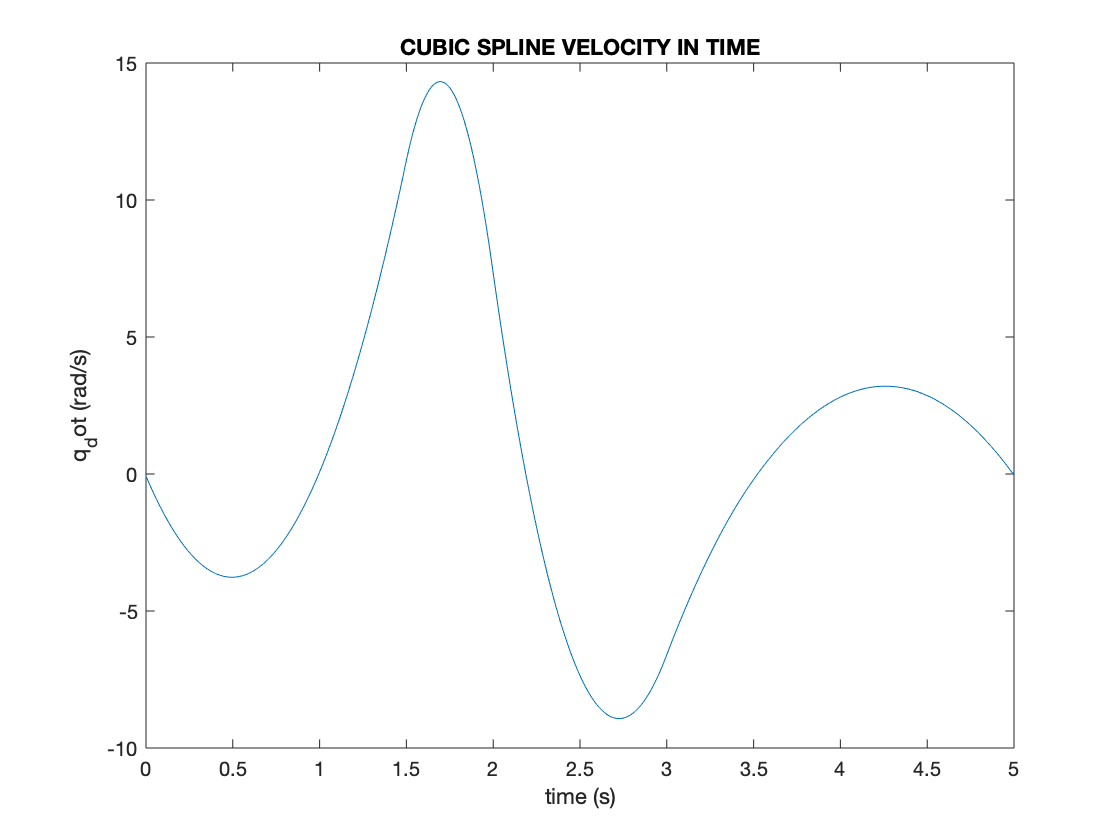

% VELOCITY
cubic_spline_vel = time_vector;

for t=1:length(lambda_vector)-1
    cubic_spline_vel(t) = (cubic_spline_traj(t+1) - cubic_spline_traj(t))/time_step;
end
cubic_spline_vel(length(lambda_vector))=cubic_spline_vel(length(lambda_vector)-1);

plot(time_vector,cubic_spline_vel)
title('CUBIC SPLINE VELOCITY IN TIME')
xlabel('time (s)')
ylabel('q_dot (rad/s)')

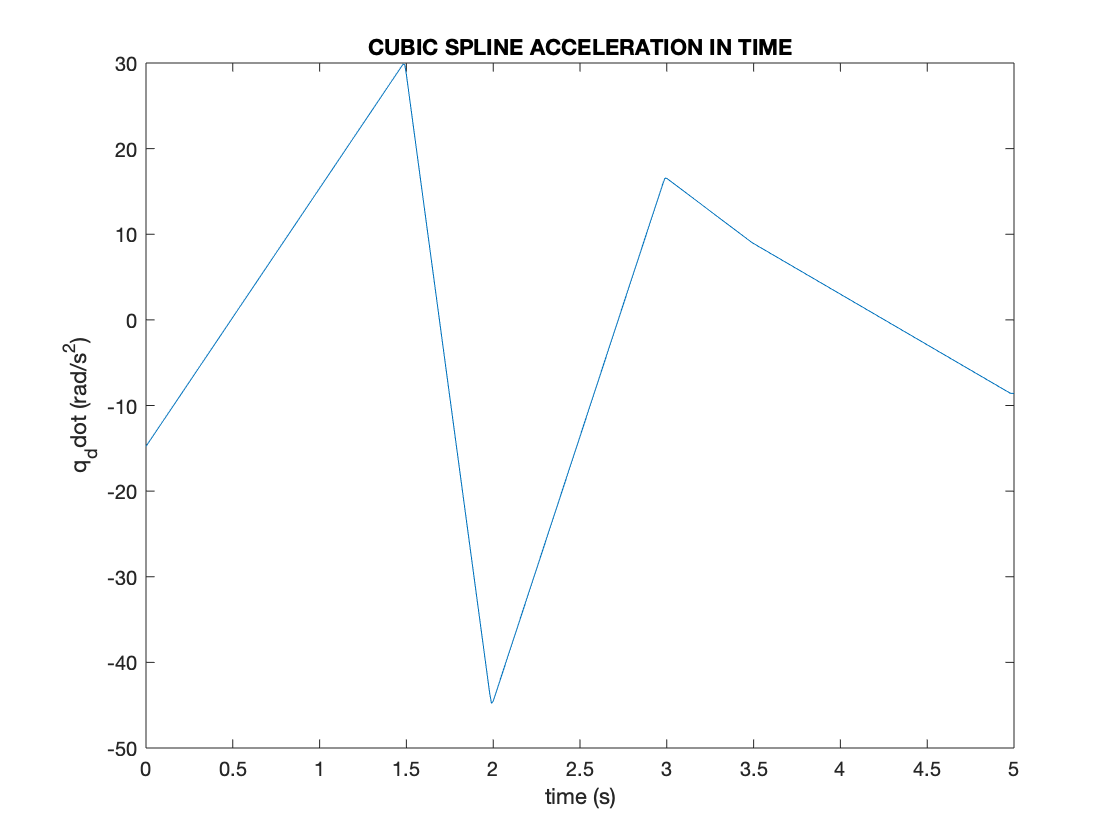


% ACCELERATION
cubic_spline_acc = time_vector;

for t=1:length(lambda_vector)-2
    cubic_spline_acc(t) = (cubic_spline_vel(t+1) - cubic_spline_vel(t))/time_step;
end
cubic_spline_acc(length(lambda_vector)-1)=cubic_spline_acc(length(lambda_vector)-2);
cubic_spline_acc(length(lambda_vector))=cubic_spline_acc(length(lambda_vector)-1);

plot(time_vector,cubic_spline_acc)
title('CUBIC SPLINE ACCELERATION IN TIME')
xlabel('time (s)')
ylabel('q_ddot (rad/s^2)')